# Control de posición del variador-motor por control óptimo

# 1. Estado del arte - control optimo LQR y LQG

El método de diseño combinado de observador y realimentación de estados no es siempre el mas útil por tres dificultades obvias:

1. La traducción de especificaciones de diseño a ubicación de polos no es directa, especialmente en sistemas complejos.

2. Las ganancias de realimentación en sistemas MIMO no son únicas.

3. Los autovalores del observador deben elegirse mas rápidos que los del controlador.

En este caso se estudiara y vera que las ganancias de realimentación de estados y del observador pueden elegirse de forma que minimicen un criterio de optimizacion dado.

## 1.1 Control óptimo 

El criterio particular que el control optimo estudia es una funcionalidad cuadratica del estado y la entrada de control la cual está definidia de la siguiente manera:


$$J\left(x_{\left(t\right)} ,u_{\left(t\right)} \right)=\int_t^T \left\lbrack x_{\left(\tau \right)}^T {\textrm{Qx}}_{\left(\tau \right)} +u_{\left(\tau \right)}^T {\textrm{Ru}}_{\left(\tau \right)} \right\rbrack d\tau$$


**Funcion de coste**

donde Q y R son matrices constantes (aunque no necesariamente) semi-definida y definida positivas respectivamente.

El control que se obtiene de minimizar este criterio es lineal. Como el criterio se basa en funcionales cuadraticos, el método se conoce como lineal-cuadratico (**LQ** linear-quadratic), del que se obtiene el regulador lineal cuadratico (LQR).

Criterios similares de optimización se siguen para el diseño de observadores, solo que el funcional depende del error de estimación, y se basa en una caracterización estadística de los ruidos que afectan al sistema. Este estimador óptimo lineal-cuadratico se conoce como el filtro de Kalman.

Cuando se combinan la ganancia de realimentacion de estados LQ con el filtro de Kalman, obtenemos lo que se conoce como un controlador lineal-cuadratico-gaussiano (**LQG**). (Lo de gaussiano viene de la caracterización estadística del ruido empleado.)

## 1.2 Control LQR estacionario

### **1.2.1. Control LQ de Horizonte Infinito**

Queremos controlar el sistema:


$${\overset{\ldotp }{X} }_{\left(t\right)} ={\textrm{Ax}}_{\left(t\right)} +{\textrm{Bu}}_{\left(t\right)}$$


con una realimentación estática de estados $u\left(t\right)=-\textrm{Kx}\left(t\right)$ tal que se minimice la función de costo


$$J=\int_0^{\infty } \left\lbrack x_{\left(t\right)}^T {\textrm{Qx}}_{\left(t\right)} +u_{\left(t\right)}^T {\textrm{Ru}}_{\left(t\right)} \right\rbrack \textrm{dt}$$


Con la realimentación, el sistema a lazo cerrado queda:


$${\overset{\ldotp }{X} }_{\left(t\right)} ={\left(A-\textrm{BK}\right)x}_{\left(t\right)}$$


esta ecuación es asintoticamente estable si y solo si la matriz P definida es la única solución definida positiva de la ecuación de Lyapunov.


$$\left(A-\textrm{BK}{\left.\right)}^T P+P\left(A-\textrm{BK}\right)+Q+K^{T\;\;} \textrm{RK}=0\right.$$
 

Por lo tanto, para cualquier ganancia K que estabilice asintoticamente el sistema, la matriz P solucion de la ecuación anterior dara un costo finito.

Supongamos que consideramos en particular la ganancia $K=-R^{-1} B^T P$, correspondiente al candidato a control óptimo LQ  Substituyendo esta K en la ecuación de lyapunov obtenemos la ecuación algebraica de Riccati (CARE). Por lo tanto, la solución del problema de control optimo LQ con horizonte infinito esta dado por la solución de la ecuación (CARE).

**Nota: **Con MATLAB, **K** se puede calcular con:

- ** K = lqr(A,B,Q,R)  caso continuo.**  

-  **K = dlqr(A,B,Q,R) caso discreto.**

## 1.3 Estimador optimo - Filtro de Kalman

Uno de los factores más importantes en el desempeño de sistemas de control, a menudo no tenido en cuenta, es el efecto de perturbaciones y ruido. Todos los sistemas están sujetos a ruido, sea en la forma de:

- Alinealidades de entrada no modeladas

- Dinámica no modelada

- Señales de entrada no deseadas

En esta sección trataremos algunos modelos simples de ruido y determinaremos formas de tenerlos en cuenta en el diseño de observadores y realimentación de estados. Consideraremos primero ruido perturbando la observación del estado de un sistema.

Con un modelo en ecuaciones de estado que incluye ruido, generaremos el mejor observador posible, es decir, el que mejor rechaza el efecto del ruido. Estos observadores suelen llamarse estimadores, y el particular el estimador conocido como el **filtro de Kalman**.

### 1.3.1. Modelos de sistemas con ruido


$$\begin{array}{l}
x_{k+1} ={\textrm{Ax}}_k +{\textrm{Bu}}_k +{\textrm{Gv}}_k \\
y_k ={\textrm{Cx}}_k +w_k 
\end{array}$$


Las nuevas señales de entrada $v_k$ y $w_k$ que aparecen en este modelo son procesos aleatorios, consistentes en ruido blanco estacionario, con media cero, y no correlacionados entre sí.

La entrada $v_k$ se llama ruido de planta, o de proceso, y la entrada $w_k$, que actua a la salida, ruido de medición. El ruido de planta modela el efecto de entradas ruidosas que actúan en los estados mismos, mientras que el ruido de medición modela efectos tales como ruido en los sensores. La entrada $u_k$ es la habitual entrada de control, considerada determinística.

### **1.3.2. Filtro de Kalman discreto**

Reconsideramos nuestra derivación anterior del observador, esta vez tomando en cuenta los efectos de ruido en la selección de la matriz de ganancia L. Esta matriz debera elegirse de forma de dar la mejor estima del estado del sistema rechazando al mismo tiempo cualquier influencia de los ruidos $v_k$ y $w_k$. La elección que haremos define el observador óptimo conocido como filtro de Kalman. Hay varias formas de derivar el filtro de Kalman. Vamos a presentar una variante basada en un observador modificado, llamado observador actual, que permite una simplificación en las derivaciones

**Procedimiento para computar el filtro de Kalman **

Partimos del conocimiento de las propiedades estadísticas, valor esperado y varianza, de los ruidos $v_k$ y $w_k$, y la condición inicial x0.

1. Calculamos la estima a **priori** del estado (predicción)


$${\overset{\vee }{x} }_{k+1} =A\overset{\wedge }{x_k } +{\textrm{Bu}}_k$$


inicializada con la estima inicial $x_{\textrm{k0}} =E_{\left\lbrack \textrm{X0}\right\rbrack }$.

2. Calculamos la ganancia de Kalman con:


$$L_{k+1} =\left\lbrack {\textrm{AS}}_K A^T +{\textrm{GVG}}^T \right\rbrack C^T {\left\lbrack C\left\lbrack {\textrm{AS}}_K A^T +{\textrm{GVG}}^T \right\rbrack C^T +W\right\rbrack }^{-1}$$


que inicializamos con la covarianza original $S_{\textrm{K0}} =E\left\lbrack x_0 x_0^T \right\rbrack =S_0$.

3. Calculamos la estima a** posterior**i, corregida con la salida medida $y_{k+1}$.


$${\overset{\wedge }{x} }_{k+1} ={\overset{\vee }{x} }_{k+1} +L_{k+1} \left\lbrack y_{k+1} -C{\overset{\vee }{x} }_{k+1} \right\rbrack$$


4. Calculamos, la matriz de covarianza para la proxima iteración.


$$S_{k+1} ={\left\lbrack I-L_{k+1} C\right\rbrack }^T \left\lbrack {\textrm{AS}}_k A^T +{\textrm{GVG}}^T \right\rbrack {\left\lbrack I-L_{k+1} C\right\rbrack }^T +L_{k+1} {\textrm{WL}}_{k+1}^T$$


y el proceso se repite el siguiente paso.

## 1.4 Filtro de Kalman estacionario

En MATLAB, la función kalman computa el filtro de Kalman estacionario (continuo o discreto).

**DLQE:** Diseño de filtro de Kalman para sistemas discretos. La función **L = dlqe(A,G,C,Q,R) **calcula la ganancia **L** del filtro de Kalman estacionario.


$$\begin{array}{l}
{\overset{\vee }{x} }_{k+1} =A{\overset{\wedge }{x} }_k +{\textrm{Bu}}_k \\
{\overset{\wedge }{x} }_{k+1} ={\overset{\vee }{x} }_{k+1} +L\left(y_{k+1} -C{\overset{\wedge }{x} }_k -{\textrm{Du}}_k \right)
\end{array}$$


para estimar el estado x del sistema en tiempo discreto


$$\begin{array}{l}
x_{k+1} ={\textrm{Ax}}_k +{\textrm{Bu}}_k +{\textrm{Gw}}_k \\
y_k ={\textrm{Cx}}_k +{\textrm{Du}}_k +v_k 
\end{array}$$


donde ***w*** y ***v*** son ruidos de proceso y de medición, respectivamente, de media nula y con covarianzas.

${\textrm{Eww}}^T =Q$    ;    ${\textrm{Evv}}^T =R$    ;     ${\textrm{Ewv}}^T =0$  

Notar que si ***w*** y ***v*** son no correlacionados (como generalmente se asume), entonces **N = 0**.

# 2. Modelo matemático de la planta y análisis

En esta parte el análisis de la planta es el mismo realizado para el realizado en la realimentación de estados

## 2.1 Función de transferencia

Entrada de la función de transferencia experimental es voltaje y la salida velocidad angular [rad/seg]. La función que se obtuvo es como sigue:


$$\frac{\Omega \left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^2 +5\ldotp 163*s+15\ldotp 58}\;\left\lbrack \frac{\textrm{rad}/\textrm{seg}}{V}\right\rbrack$$


f_motor_rad=tf(26.55,[1 5.163 15.58])

f_motor_rad =
 
          26.55
  ---------------------
  s^2 + 5.163 s + 15.58
 
Continuous-time transfer function.
Model Properties


Se comprueba estabilidad BIBO, es decir, los polos deben tener parte real negativa:

pole(f_motor_rad)

ans =   -2.5815 + 2.9859i
  -2.5815 - 2.9859i


Queda así comprobado la estabilidad BIBO, con lo que la respuesta ante la entrada escalón debe tener respuesta en estado estacionario:

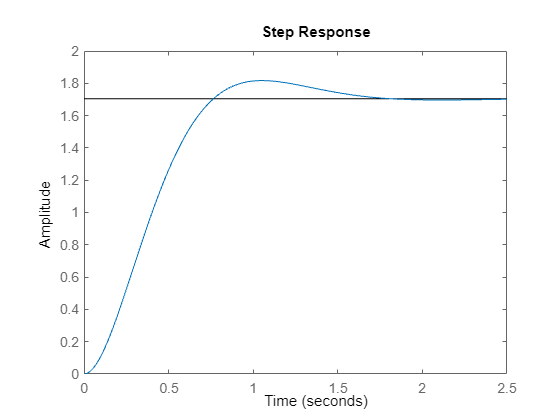

step(f_motor_rad)

La función de transferencia mostrada es una que relaciona la velocidad angular y el voltaje aplicado a la entrada del variador de frecuencia, sin embargo, para realizar un control de posición va a ser necesario obtener una función de transferencia que relaciona la posición y el voltaje de entrada. Para este propósito se parte de que la velocidad angular es la primera derivada de la posición angular:


$$\frac{\Omega \left(s\right)}{V\left(s\right)}=\frac{\dot{\Theta} \left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^2 +5\ldotp 163*s+15\ldotp 58}\;\left\lbrack \frac{\textrm{rad}/\textrm{seg}}{V}\right\rbrack$$


Aplicando el teorema de diferenciación real de la transformada de Laplace se obtiene:


$$\dot{\Theta} \left(s\right)=s\Theta \left(s\right)-\theta \left(0\right)$$


Se va a considerar que las condición inicial de posición es cero, es decir, el proceso inicia con un ángulo de cero radianes:


$$\dot{\Theta} \left(s\right)=s\Theta \left(s\right)$$


s=tf('s');  
pos_mot_rad=f_motor_rad/s

pos_mot_rad =
 
            26.55
  -------------------------
  s^3 + 5.163 s^2 + 15.58 s
 
Continuous-time transfer function.
Model Properties


De igual manera que antes, se comprueba la estabilidad BIBO:

pole(pos_mot_rad)

ans =    0.0000 + 0.0000i
  -2.5815 + 2.9859i
  -2.5815 - 2.9859i


En este caso no se comprueba estabilidad BIBO, por lo que ante una entrada escalón no se alcanzara el régimen permanente:

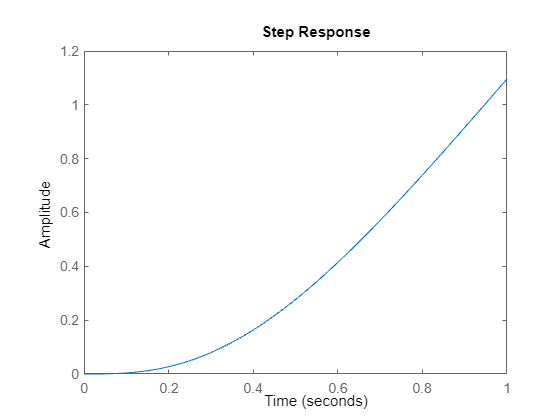

step(pos_mot_rad,1)

Se comprueba lo anteriormente dicho, sin embargo, este se trata de un sistema de tipo 1, por lo que se puede revisar el comportamiento en lazo cerrado con realimentación unitaria, donde podría estabilizarse y no tener error en estado estacionario:

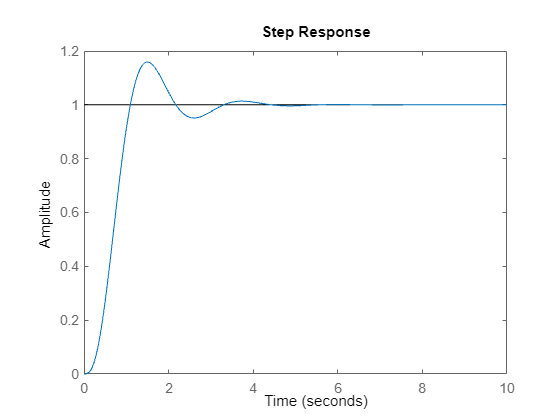

step(feedback(pos_mot_rad,1),10)

stepinfo(feedback(pos_mot_rad,1))

ans = struct with fields:
         RiseTime: 0.6615
    TransientTime: 3.0580
     SettlingTime: 3.0580
      SettlingMin: 0.9144
      SettlingMax: 1.1592
        Overshoot: 15.9186
       Undershoot: 0
             Peak: 1.1592
         PeakTime: 1.5056


Lo último dicho se comprueba, además, a simple vista se puede suponer que no existe error en estado estacionario, y utilizando MATLAB se comprueba completamente:

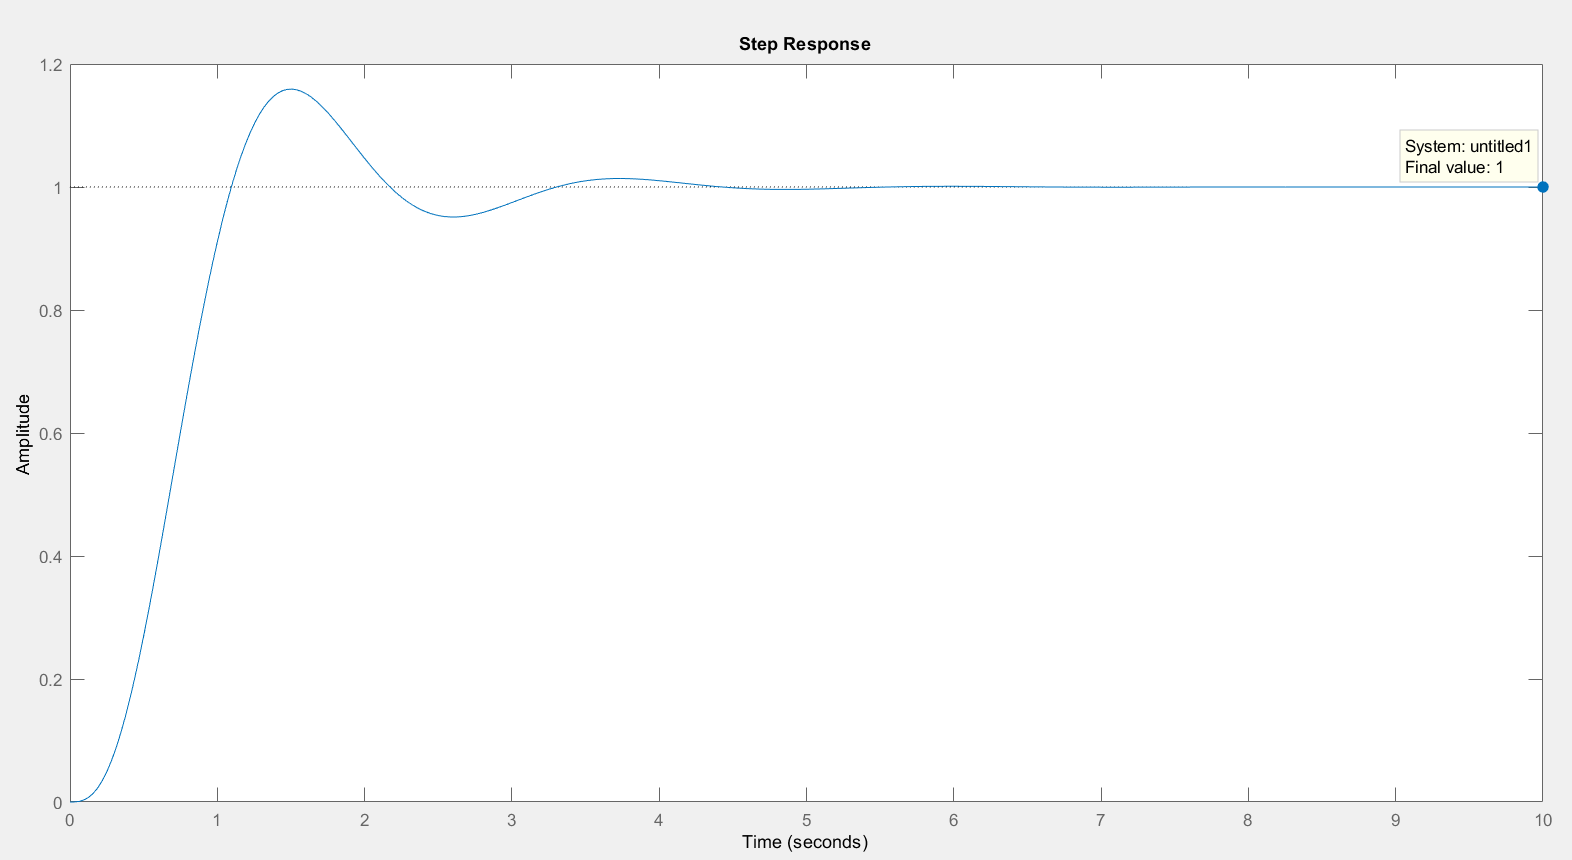

Esto nos dice que sobre esta planta se podría aplicar, más adelante, realimentación de estados con seguimiento robusto sin necesidad de agregar un integrador extra (servosistema tipo 1 con integrador en la planta)[1][2].

Hasta ahora se ha mostrado funciones de transferencia con unidades en radianes y la función que relaciona la posición, relaciona la posición angular. Pero, para los fines de la unidad de selección, es más útil tener una función de transferencia que relaciona la posición lineal, y que esta se encuentre en unidades que resulten fáciles de manejar, para esto último las unidades más sencillas de manejar son los centímetros.

Para poder relacionar la posición lineal de la cinta transportadora que se encuentra sobre eje del motor, se va a tener que suponer que no existen retardos de transporte (despreciables) sobre toda la cinta transportadora (suponer que esta es inextensible) y que la velocidad lineal del eje del motor es la misma velocidad que tendrá la cinta. Con estas suposiciones podemos decir que la longitud de arco del eje del motor y el desplazamiento de la cinta transportadora son idénticos.

Sabiendo que la longitud de arco es igual a:


$$L=r\;\theta$$


Se debe determinar el radio del eje del motor que está sujeto a la cinta transportadora, realizando mediciones simples se puede aproximar el radio a:


$$r=1\ldotp 8382\;\left\lbrack \textrm{cm}\right\rbrack$$


Por lo tanto, aplicando la ecuación de la longitud de arco sobre la función de transferencia:


$$\frac{L\left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^3 +5\ldotp 163*s^2 +15\ldotp 58*s}*1\ldotp 8382\left\lbrack \frac{\textrm{cm}}{V}\right\rbrack$$


pos_mot=pos_mot_rad*1.8382

pos_mot =
 
            48.8
  -------------------------
  s^3 + 5.163 s^2 + 15.58 s
 
Continuous-time transfer function.
Model Properties


Como tal, se está aplicando un escalamiento adecuándose la función de transferencia mediante la ecuación lineal de longitud de arco y con las unidades que queremos manejar (centímetros), por lo cual las características dinámicas no se ven alteradas más allá de la ganancia de la función de transferencia.

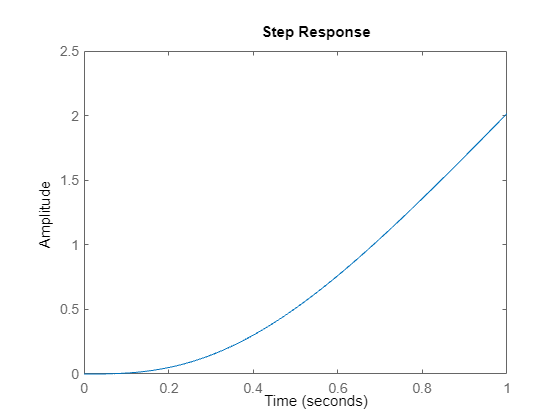

step(pos_mot,1)

## 2.2 Modelo en el espacio de estados 

Para hallar el modelo en espacio de estados podemos partir de la ecuación diferencial lineal estacionaria que modela al sistema a partir de la función de transferencia obtenida:


$$\frac{L\left(s\right)}{V\left(s\right)}=\frac{48\ldotp 8042}{s^3 +5\ldotp 163*s^2 +15\ldotp 58*s}$$


Por comodidad:


$$\begin{array}{l}
a=48\ldotp 8042\\
b=5\ldotp 1630\\
c=15\ldotp 58\\
\frac{L\left(s\right)}{V\left(s\right)}=\frac{a}{s^3 +b*s^2 +c*s}
\end{array}$$


## 
$${\overset{\ldotp \ldotp \ldotp }{l} }_{\left(t\right)} +b*{\overset{\ldotp \ldotp }{l} }_{\left(t\right)} +c*{\overset{\ldotp }{l} }_{\left(t\right)} =a*v_{\left(t\right)}$$


Eligiendo las variables de estado como:


$$\begin{array}{l}
x_1 =l_{\left(t\right)} \;\;\textrm{Posición}\\
x_2 ={\dot{l} }_{\left(t\right)} \;\;\textrm{Velocidad}\\
x_3 ={\overset{\ldotp \ldotp }{l} }_{\left(t\right)} \;\;\textrm{Aceleración}
\end{array}$$


El modelo en variables de estado queda como:


$${\dot{x} }_{\left(t\right)} =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
0 & -c & -b
\end{array}\right\rbrack x_{\left(t\right)} +\left\lbrack \begin{array}{c}
0\\
0\\
a
\end{array}\right\rbrack v_{\left(t\right)}$$



$${\dot{x} }_{\left(t\right)} =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
0 & -15\ldotp 58 & -5\ldotp 163
\end{array}\right\rbrack x_{\left(t\right)} +\left\lbrack \begin{array}{c}
0\\
0\\
48\ldotp 8042
\end{array}\right\rbrack v_{\left(t\right)}$$


[num,den]=tfdata(pos_mot);
num=cell2mat(num);
den=cell2mat(den);
a=num(4)

a = 48.8042

b=den(2)

b = 5.1630

c=den(3)

c = 15.5800


Ac=[0 1 0
   0 0 1
   0 -c -b];
Bc=[0
   0
   a];
Cc=[1 0 0];

Dc=0;
EE=ss(Ac,Bc,Cc,Dc)

EE =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3       0  -15.58  -5.163
 
  B = 
         u1
   x1     0
   x2     0
   x3  48.8
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


En este caso se puede realizar el análisis de estabilidad interna, se puede aplicar la función de Lyapunov para sistemas lineales o, como en este caso, revisar el valor de los autovalores de la matriz A, los que deben tener parte real negativa:

eig(Ac)

ans =    0.0000 + 0.0000i
  -2.5815 + 2.9859i
  -2.5815 - 2.9859i


En este caso no se comprueba la estabilidad interna, esto se puede evidenciar que al revisar la respuesta ante condiciones iniciales distintas de cero (y sin entrada de excitación externa) el estado x1 (posición) no tiene asintóticamente a cero, al contrario los estados de velocidad y aceleración que si tienden asintóticamente a cero. Entonces, con el control que se aplique se debe procurar estabilizar al sistema.

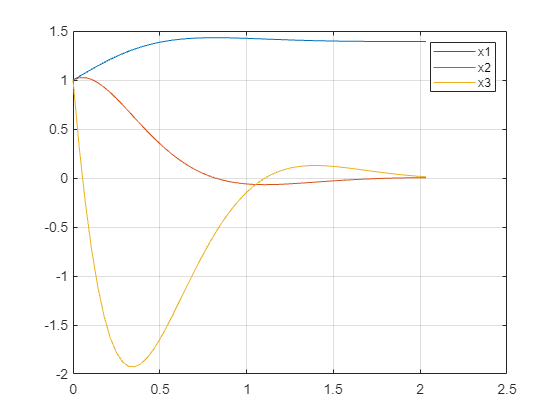

[y,t,x]=initial(ss(EE.A,EE.B,EE.C,EE.D),[1 1 1]');
plot(t,x(:,1))
hold on
plot(t,x(:,2))
plot(t,x(:,3))
hold off
grid on
legend('x1','x2','x3')

# 3. Control óptimo

## 3.1 Ley de control

Se va a utilizar el control por realimentación de estados, inicialmente partimos de la ley de control para un sistema seguidor:


$$u_{\left(t\right)} =Nr_{\left(t\right)} -Kx_{\left(t\right)}$$


Pero, al tratarse de un sistema de tipo 1, se puede utilizar una ley de control para un sistema de seguimiento robusto y sin necesidad de agregar un estado extra (integrador):


$$u_{\left(t\right)} =k_1 r_{\left(t\right)} -Kx_{\left(t\right)}$$


Donde:


$$K=\left\lbrack \begin{array}{ccccc}
k_1  & k_2  & k_3  & \ldotp \ldotp \ldotp  & k_n 
\end{array}\right\rbrack$$


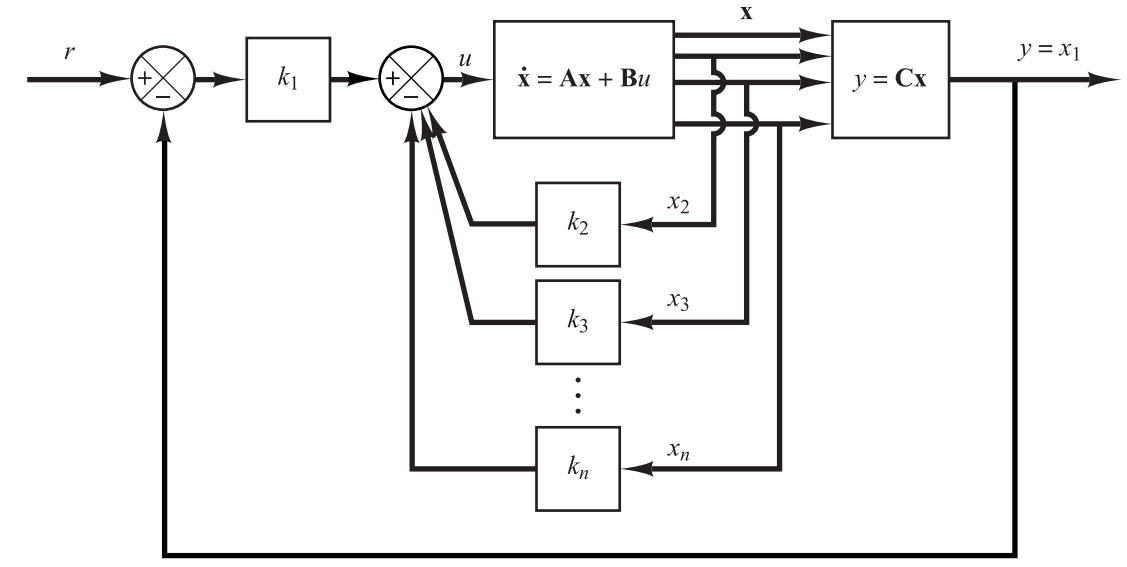

## 3.2 Determinación de la matriz de ganancia de realimentación de estado y filtro de Kalman

Discretización del modelos en espacio de estados continuo a discreto incluyendo el ruido


$$\check{X} {\left[k\right]}=A*\hat{X} {\left[k-1\right]}+B*u\left\lbrack k\right\rbrack$$



$${\left[\begin{array}{c}
{\check{X} }_1 \left\lbrack k\right\rbrack \\
{\check{X} }_2 \left\lbrack k\right\rbrack \\
{\check{X} }_3 \left\lbrack k\right\rbrack 
\end{array}\right]}={\left[\begin{array}{ccc}
1 & 0.027 & 0.0003\\
0 & 0.9946 & 0.0252\\
0 & -0.319 & 0.8647
\end{array}\right]}*{\left[\begin{array}{c}
{\hat{X} }_1 \left\lbrack k-1\right\rbrack \\
{\hat{X} }_2 \left\lbrack k-1\right\rbrack \\
{\hat{X} }_3 \left\lbrack k-1\right\rbrack 
\end{array}\right]}+{\left[\begin{array}{c}
0.0002\\
0.017\\
1.2277
\end{array}\right]}*u_{\left\lbrack k\right\rbrack }$$


%% Discretizar el modelo en espacio de estados e incluir el ruido
%******* Matrices de ganancia de ruido G y H **********
Gc=[1;1;1];
H=1;
%***************************************************************
Ts=27e-3;
%matrices A y B
[A,B]=c2d(Ac,Bc,Ts)

A =     1.0000    0.0270    0.0003
         0    0.9946    0.0252
         0   -0.3919    0.8647


B =     0.0002
    0.0170
    1.2277


%matrices A y G (ruido)
[A,G]=c2d(Ac,Gc,Ts)

A =     1.0000    0.0270    0.0003
         0    0.9946    0.0252
         0   -0.3919    0.8647


G =     0.0274
    0.0273
    0.0197


C=Cc;
D=Dc;

Definimos las covarianzas y determinamos la ganancia de Kalman de estado estacionario


$${\left[\begin{array}{c}
{\check{X} }_1 \left\lbrack k\right\rbrack \\
{\check{X} }_2 \left\lbrack k\right\rbrack \\
{\check{X} }_3 \left\lbrack k\right\rbrack 
\end{array}\right]}={\left[\begin{array}{ccc}
1 & 0.027 & 0.0003\\
0 & 0.9946 & 0.0252\\
0 & -0.319 & 0.8647
\end{array}\right]}*{\left[\begin{array}{c}
{\hat{X} }_1 \left\lbrack k-1\right\rbrack \\
{\hat{X} }_2 \left\lbrack k-1\right\rbrack \\
{\hat{X} }_3 \left\lbrack k-1\right\rbrack 
\end{array}\right]}+\left\lbrack \begin{array}{cc}
0\ldotp 0002 & 0\ldotp 0274\\
0\ldotp 017 & 0\ldotp 0273\\
1\ldotp 2277 & 0\ldotp 0197
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
u_{1\left(k\right)} \\
u_{2\left(k\right)} 
\end{array}\right\rbrack$$



$$y_{k-1} =\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack *{\left[\begin{array}{c}
{\hat{X} }_1 \left\lbrack k-1\right\rbrack \\
{\hat{X} }_2 \left\lbrack k-1\right\rbrack \\
{\hat{X} }_3 \left\lbrack k-1\right\rbrack 
\end{array}\right]}+\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
u_{1\left(k\right)} \\
u_{2\left(k\right)} 
\end{array}\right\rbrack$$


**Modelo del sistema más ruido (DISCRETO)**

Con el modelo hallado procedemos a hallar la matriz **L** con la ecuación discreta de Riccati 


$$L=\left({\textrm{APC}}^T +\overset{-}{N} \right)\left({\textrm{CPC}}^T +\overset{-}{R} \right)-1$$


donde:


$$\overset{-}{R} =R+\textrm{HN}+N^T H^T +{\textrm{HQH}}^T$$



$$\overset{-}{N} =G\left({\textrm{QH}}^T +N\right)$$


los valores de **A,B,C,R,N,H,Q** y **G** son conocidos por lo cual lo que se debe hacer es remplazar en las formulas y hallar los valores de **P** y **L**.

                
$$L=\left\lbrack \begin{array}{c}
0\ldotp 0212\\
0\ldotp 0149\\
0\ldotp 0059
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\wedge \;\;\;\;\;\;\;\;\;\;\;P=\left\lbrack \begin{array}{ccc}
0\ldotp 0153 & 0\ldotp 0030 & -0\ldotp 0077\\
0\ldotp 0030 & 0\ldotp 0040 & -0\ldotp 0053\\
-0\ldotp 0077 & -0\ldotp 0053 & 0\ldotp 0179
\end{array}\right\rbrack \;\;$$


%% Definir covarianzas y determinar la ganancia de Kalman est. estacionario
%******* Covarianzas ******
V=1;    %covarianza para el ruido del proceso
w=1;    %covarianza para el ruido de medición
%***************************
EE_noise=ss(A,[B G],C,[D H],Ts); %modelo discreto del sistema con ruido
Q=V;
R=w;
N=0;
[kest,L,P]=kalman(EE_noise,Q,R,N); %Ganancia de Kalman

Verificamos lo realizado con el diseño del filtro:

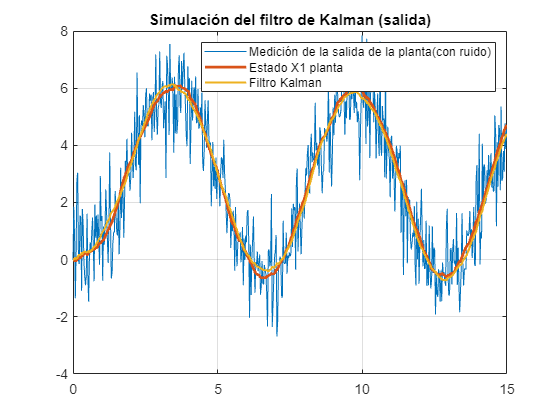

%% Simulación DEL FILTRO DE KALMAN
t=0:Ts:15;
u=sin(t);   %Funcion de Prueba
x0=[0;0;0]; %estados iniciales
x=x0;
y=C*x0;
xh=[0;0;0]; %estado estimado a priori inicial
xp=xh;      %estado estimado a posteiori inicial
 
for k=1:length(t)-1
    x(:,k+1)=A*x(:,k)+B*u(k)+G*sqrt(V)*randn;
    y(k+1)=C*x(:,k+1)+sqrt(w)*randn;
    xp(:,k+1)=A*xh(:,k)+B*u(k);
    xh(:,k+1)=xp(:,k+1)+L*(y(k)-C*xh(:,k));
end
 
plot(t,y)
grid on
title('Simulación del filtro de Kalman (salida)')
hold on
plot(t,x(1,:),'LineWidth',2)
hold on
plot(t,xh(1,:),'LineWidth',1.5)
hold off
legend('Medición de la salida de la planta(con ruido)','Estado X1 planta','Filtro Kalman')

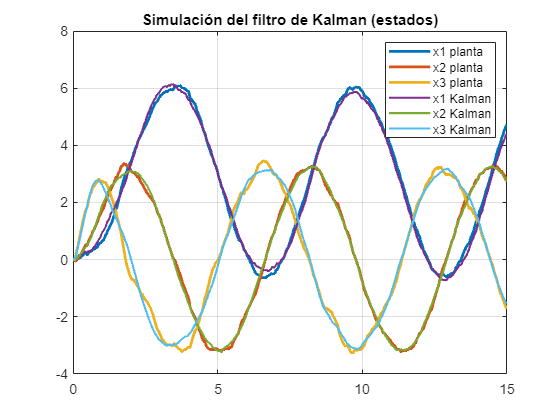

 
plot(t,x(1,:),'LineWidth',2)
title('Simulación del filtro de Kalman (estados)')
grid on
hold on 
plot(t,x(2,:),'LineWidth',2)
plot(t,x(3,:),'LineWidth',2)
plot(t,xh(1,:),'LineWidth',1.5)
plot(t,xh(2,:),'LineWidth',1.5)
plot(t,xh(3,:),'LineWidth',1.5)
legend('x1 planta','x2 planta','x3 planta','x1 Kalman','x2 Kalman','x3 Kalman')
hold off

Ahora lo que se hace es hallar la ganancia de realimentación optima K:

esta ganancia de realimentación optima se la obtine con las siguientes ecuaciones:


$$\left(A-\textrm{BK}{\left.\right)}^T P+P\left(A-\textrm{BK}\right)+Q+K^{T\;\;} \textrm{RK}=0\right.$$



$$K=-R^{-1} B^T P$$


Donde:


$$Q=\left\lbrack \begin{array}{ccc}
2 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\wedge \;\;\;\;\;\;\;\;\;R=2$$


nuestro objetivo es hallar las matices K y P


$$K=\left\lbrack \begin{array}{ccc}
0\ldotp 6958 & 0\ldotp 6979 & 0\ldotp 4243
\end{array}\right\rbrack$$


**Gnanacia de realimentacion optima**


$$P=\left\lbrack \begin{array}{ccc}
2\ldotp 8966 & 1\ldotp 4966 & 0\ldotp 0422\\
1\ldotp 4956 & 2\ldotp 0562 & 0\ldotp 0479\\
0\ldotp 0422 & 0\ldotp 0479 & 0\ldotp 0271
\end{array}\right\rbrack$$


**Matriz P**

%% Determinación de la ganancia de realimentación 
% de estados optima (LQR estacionario)
q1=2;
q2=1;
q3=1;
Q=[q1 0 0
   0 q2 0
   0 0 q3]

Q =      2     0     0
     0     1     0
     0     0     1


R=2;
[K,P]=lqrd(Ac,Bc,Q,R,Ts)

K =     0.6958    0.6979    0.4243


P =     2.8966    1.4956    0.0422
    1.4956    2.0562    0.0479
    0.0422    0.0479    0.0271


EE_lazo=ss(A-B*K,B*K(1),C,D,Ts)

EE_lazo =
 
  A = 
              x1         x2         x3
   x1     0.9999    0.02684  0.0002822
   x2   -0.01181     0.9827    0.01795
   x3    -0.8542     -1.249     0.3438
 
  B = 
              u1
   x1  0.0001076
   x2    0.01181
   x3     0.8542
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.027 seconds
Discrete-time state-space model.


stepinfo(EE_lazo)

ans = struct with fields:
         RiseTime: 2.2140
    TransientTime: 3.5100
     SettlingTime: 3.5100
      SettlingMin: 0.9023
      SettlingMax: 1.0071
        Overshoot: 0.7065
       Undershoot: 0
             Peak: 1.0071
         PeakTime: 4.9680


Una vez obtenida la ganancia de realimentación simulamos lo obtenido junto al filtro de Kalman y verificamos la respuesta que obtenemos:

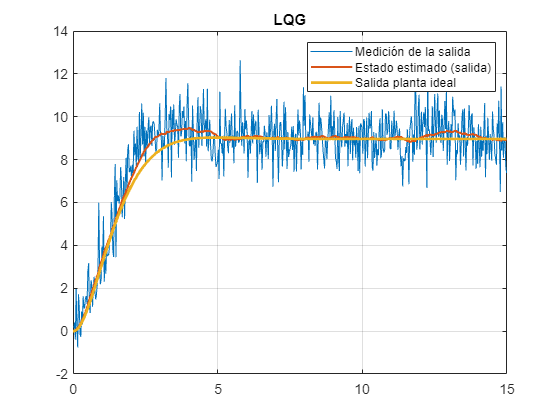

%% Simulación del sistema a lazo cerrado con el filtro de Kalman (LQG)
w=1;
V=1;
t=0:Ts:15;
x0=[0.2;0;0];                %estados iniciales
x=x0;
y=C*x0;
r=8.5*1.055;                  %Referencia
[yp,tp]=step(r*EE_lazo,15);  %Respuesta ideal
xh=[0;0;0];                  %estado estimado a priori inicial
xp=xh;                       %estado estimado a posteiori inicial
for k=1:length(t)-1
    u(k)=r*K(1) - K*xh(:,k); %señal de control
    %Modelo de la planta con ruido
    x(:,k+1)=A*x(:,k)+B*u(k)+G*sqrt(V)*randn;
    y(k+1)=C*x(:,k+1)+sqrt(w)*randn;
    %Filtro de Kalman de estado estacionario (matricial)
    xp(:,k+1)=A*xh(:,k)+B*u(k);
    xh(:,k+1)=xp(:,k+1)+L*(y(k)-C*xh(:,k));
end
plot(t,y)
grid on
title('LQG')
hold on
plot(t,xh(1,:),'LineWidth',1.5)
plot(tp,yp,'LineWidth',2)
hold off
legend('Medición de la salida','Estado estimado (salida)','Salida planta ideal')

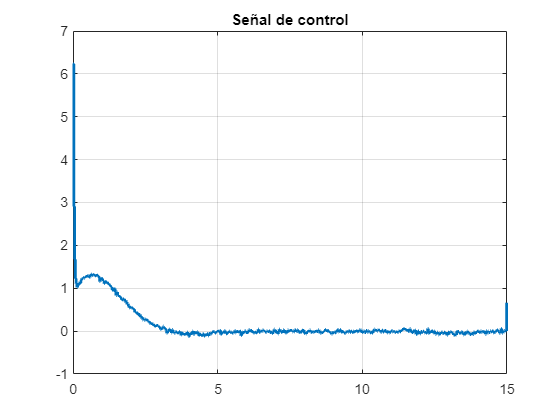

stairs(t,u,'LineWidth',2)
grid on
title('Señal de control')

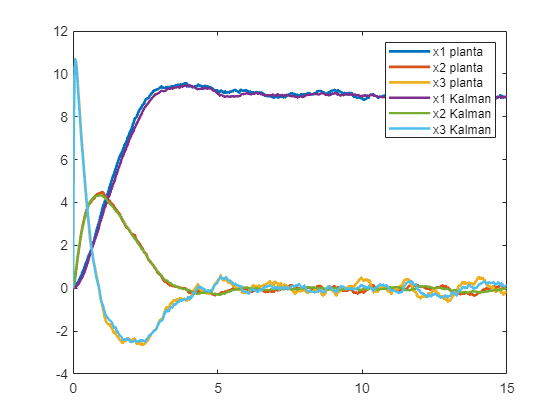

plot(t,x(1,:),'LineWidth',2)
hold on 
plot(t,x(2,:),'LineWidth',2)
plot(t,x(3,:),'LineWidth',2)
plot(t,xh(1,:),'LineWidth',1.8)
plot(t,xh(2,:),'LineWidth',1.8)
plot(t,xh(3,:),'LineWidth',1.8)
legend('x1 planta','x2 planta','x3 planta','x1 Kalman','x2 Kalman','x3 Kalman')
hold off

## 3.3 Ecuaciones en recurrencia para implementación en PLC

Para las ecuaciones en recurrencia a implementar en el PLC se utilizan las siguientes ecuaciones:

Modelo matricial de la estimación con el filtro de Kalman:


$$\check{X} {\left[k\right]}=A*\hat{X} {\left[k-1\right]}+B*u\left\lbrack k\right\rbrack$$



$${\left[\begin{array}{c}
{\check{X} }_1 \left\lbrack k\right\rbrack \\
{\check{X} }_2 \left\lbrack k\right\rbrack \\
{\check{X} }_3 \left\lbrack k\right\rbrack 
\end{array}\right]}={\left[\begin{array}{ccc}
1 & 0.027 & 0.0003\\
0 & 0.9946 & 0.0252\\
0 & -0.319 & 0.8647
\end{array}\right]}*{\left[\begin{array}{c}
{\hat{X} }_1 \left\lbrack k-1\right\rbrack \\
{\hat{X} }_2 \left\lbrack k-1\right\rbrack \\
{\hat{X} }_3 \left\lbrack k-1\right\rbrack 
\end{array}\right]}+{\left[\begin{array}{c}
0.0002\\
0.017\\
1.2277
\end{array}\right]}*u\left\lbrack k\right\rbrack$$



$${\left[\begin{array}{c}
{\check{X} }_1 \left\lbrack k\right\rbrack \\
{\check{X} }_2 \left\lbrack k\right\rbrack \\
{\check{X} }_3 \left\lbrack k\right\rbrack 
\end{array}\right]}={\left[\begin{array}{c}
{\hat{X} }_1 {\left[k-1\right]}+0.027{*\hat{X} }_2 {\left[k-1\right]}+{0.0003*\hat{X} }_3 {\left[k-1\right]}+0.0002*u\left\lbrack k\right\rbrack \\
0.9946{*\hat{X} }_2 {\left[k-1\right]}+{0.0252*\hat{X} }_3 {\left[k-1\right]}+0.017*u\left\lbrack k\right\rbrack \\
-0.319{*\hat{X} }_2 {\left[k-1\right]}+{0.8647*\hat{X} }_3 {\left[k-1\right]}+1.2277*u\left\lbrack k\right\rbrack 
\end{array}\right]}$$


Modelo matricial de la compensación a posteriori


$$\hat{X} {\left[k\right]}=\check{X} {\left[k\right]}+L*{\left(y{\left[k-1\right]}-C*\hat{X} {\left[k-1\right]}\right)}$$



$${\left[\begin{array}{c}
{\hat{X} }_1 \left\lbrack k\right\rbrack \\
{\hat{X} }_2 \left\lbrack k\right\rbrack \\
{\hat{X} }_3 \left\lbrack k\right\rbrack 
\end{array}\right]}={\left[\begin{array}{c}
{\check{X} }_1 \left\lbrack k\right\rbrack \\
{\check{X} }_2 \left\lbrack k\right\rbrack \\
{\check{X} }_3 \left\lbrack k\right\rbrack 
\end{array}\right]}+{\left[\begin{array}{c}
0.0212\\
0.0149\\
0.0059
\end{array}\right]}*{\left(y{\left[k-1\right]}-{\left[\begin{array}{ccc}
1 & 0 & 0
\end{array}\right]}*{\left[\begin{array}{c}
{\hat{X} }_1 \left\lbrack k-1\right\rbrack \\
{\hat{X} }_2 \left\lbrack k-1\right\rbrack \\
{\hat{X} }_3 \left\lbrack k-1\right\rbrack 
\end{array}\right]}\right)}$$



$${\left[\begin{array}{c}
{\hat{X} }_1 \left\lbrack k\right\rbrack \\
{\hat{X} }_2 \left\lbrack k\right\rbrack \\
{\hat{X} }_3 \left\lbrack k\right\rbrack 
\end{array}\right]}={\left[\begin{array}{c}
{\check{X} }_1 \left\lbrack k\right\rbrack \\
{\check{X} }_2 \left\lbrack k\right\rbrack \\
{\check{X} }_3 \left\lbrack k\right\rbrack 
\end{array}\right]}+{\left[\begin{array}{c}
0.0212\\
0.0149\\
0.0059
\end{array}\right]}*{\left(y{\left[k-1\right]}-{\hat{X} }_1 \left\lbrack k-1\right\rbrack \right)}$$



$${\left[\begin{array}{c}
{\hat{X} }_1 \left\lbrack k\right\rbrack \\
{\hat{X} }_2 \left\lbrack k\right\rbrack \\
{\hat{X} }_3 \left\lbrack k\right\rbrack 
\end{array}\right]}={\left[\begin{array}{c}
{\check{X} }_1 {\left[k\right]}+0.0212*{\left(y{\left[k-1\right]}-{\hat{X} }_1 \left\lbrack k-1\right\rbrack \right)}\\
{\check{X} }_2 {\left[k\right]}+0.0149*{\left(y{\left[k-1\right]}-{\hat{X} }_1 \left\lbrack k-1\right\rbrack \right)}\\
{\check{X} }_3 {\left[k\right]}+0.0059*{\left(y{\left[k-1\right]}-{\hat{X} }_1 \left\lbrack k-1\right\rbrack \right)}
\end{array}\right]}$$


# 4. Contrastar datos con la simulación

En este caso se implementó el controlador en tiempo discreto en el PLC S7-200, entonces, se pudo obtener, mediante el uso de la instrumentación específica (osciloscopio), la señal de control proveniente de la salida analógica del PLC (DAC) y se puede comparar con la simulación de la señal de control obtenida con las simulaciones y el simulink:

Lo que haremos para la vaidacion del modelo es lo siguiente:

1. Exportar los datos tomados 

            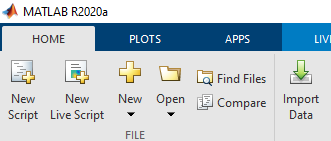

 Primero vamos a la pestaña home despues seleccionamos el icono **Import Data **una vez seguido estos pasos lo que prosigue es seleccionar el archivo donde se guardo los datos y posteriormente importar los datos del excel.

2. Tratamiento de los datos

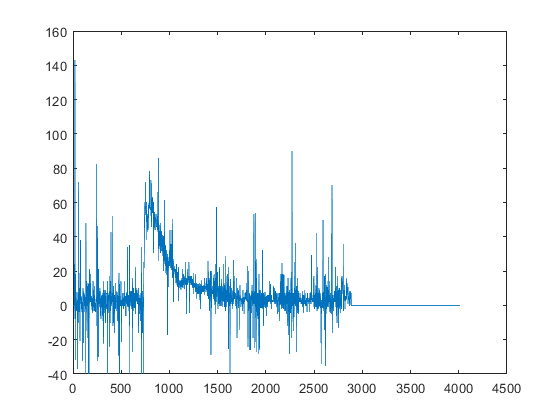

plot(lqr)

como podemos observar los datos necesitan ser tratados.

3. Pasar los datos por un filtro digital

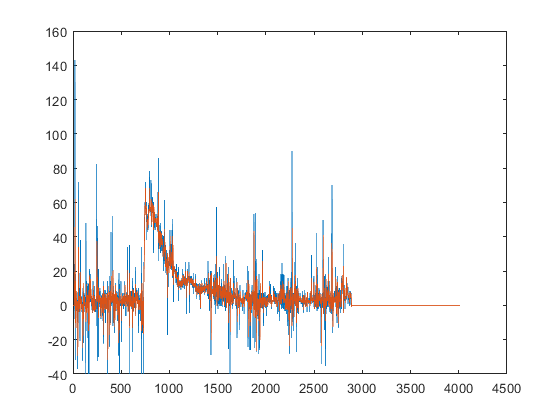

[a,b]=butter(3,0.4,'low');
fil=filter(a,b,lqr);
plot(lqr)
hold on
plot(fil)
hold off

4. Movemos la grafica en el eje X y lo llevamos al origen

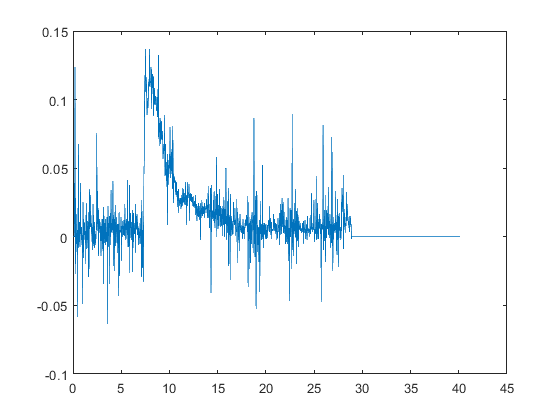

t2(1)=0;
for i=2:length(lqr)
    t2(i)=t2(i-1)+1e-2;
end
lqr2=fil*(5e-2)/25;
plot(t2,lqr2)

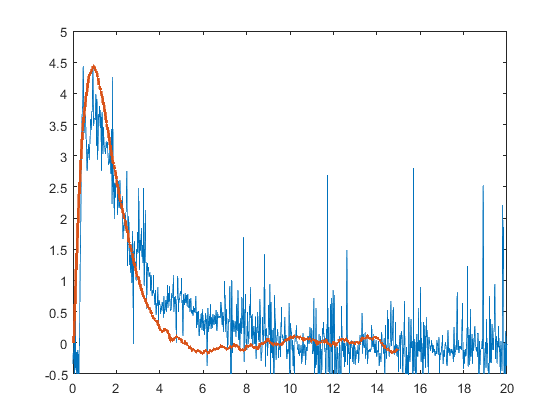

lqr3=lqr2*1.8382*pi*1.1962e3/200;
ta=find(t2>=7.02);
tb=ta(1);
lqr4=lqr3(tb:length(t2));
t3=0;
for i=2:length(lqr4)
    t3(i)=t2(i-1)+1e-2;
end
plot(t3,lqr4-0.3)
hold on
stairs(t,xh(2,:),'LineWidth',2)
axis([0 20 -0.5 5])
hold off

# 5. Referencias

[1] J. H. Braslavsky, *Notas de Clase Control Automático 2*, Universidad Nacional de Quilmes, 2001

[2] K. Ogata, *Ingeniería de control moderna*, 5a. ed. Madrid: Pearson Educación, 2010. 